**Velocity**

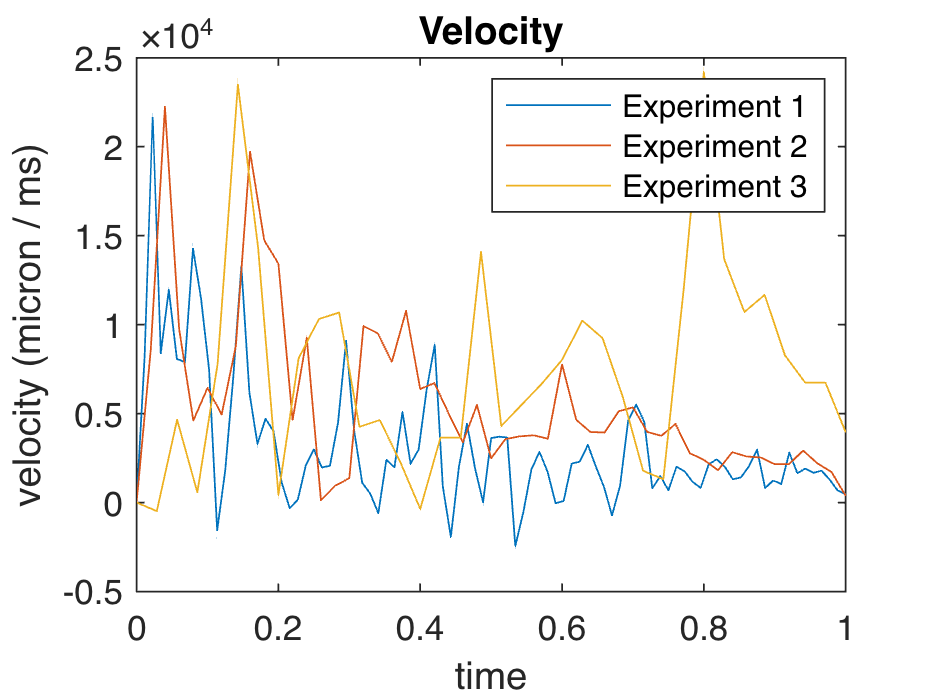

fpms = 50; %-- frames per millisecond
experiments = {experiment1 experiment2 experiment3};
micronsPerXPixel = 13.5;
micronsPerZPixel = 50;
timeSmoothing = 3;
xSmoothing = 21;
zSmoothing  = 21;

threshold = 0.985;
velocities = [{} {} {}];
areas = [{} {} {}];
perimeters = [{} {} {}];
lengths = [{} {} {}];
betas = [{} {} {}];
lineWidth = micronsPerZPixel * size(experiment1,1);

for i=1:length(experiments)
    current = SmoothExperiment(experiments{i},timeSmoothing,threshold, zSmoothing, xSmoothing);
    scaled = ScaleImage(current,micronsPerZPixel/micronsPerXPixel);
    [Area,Perimeter,Velocity,Beta] = GetParameters(scaled);
    velocities(i) = {Velocity * (micronsPerXPixel/msPerFrame)} ;
    areas(i) = {Area * micronsPerXPixel * micronsPerXPixel} ;
    perimeters(i) = {Perimeter * micronsPerXPixel} ;
    lengths(i) = {Area * micronsPerXPixel ./ Perimeter};
    betas(i) = {Beta};
end

timeLines = {linspace(0,1,89) linspace(0,1,51) linspace(0,1,36)};

for i=1:length(experiments)
    plot(timeLines{i},velocities{i});
    hold on;
end
hold off;
legend("Experiment 1", "Experiment 2", "Experiment 3");
title("Velocity");
xlabel("time");
ylabel("velocity (micron / ms)");

**Area**

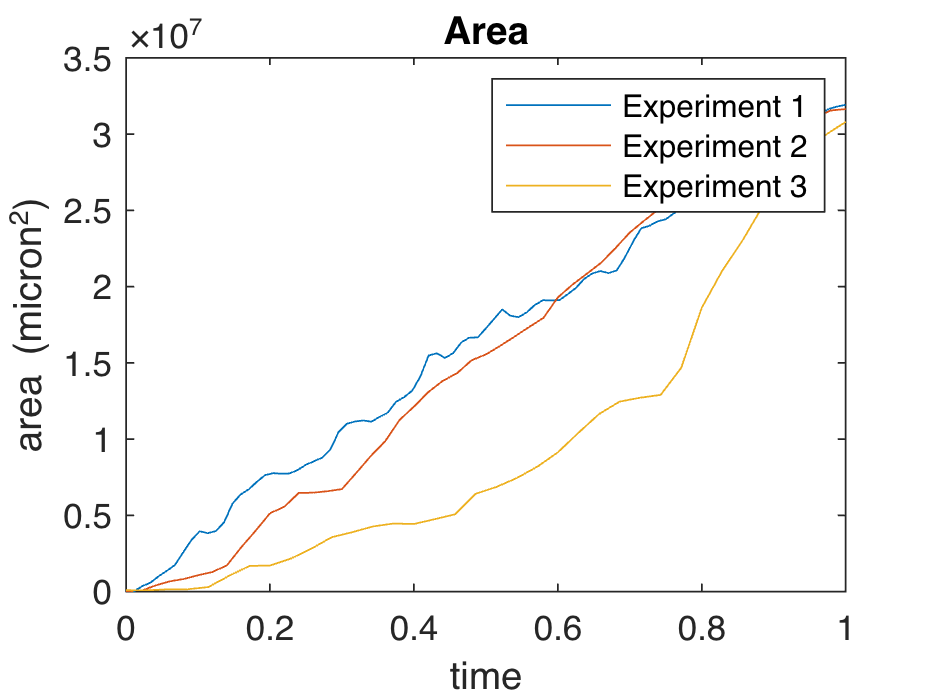

for i=1:length(experiments)
    plot(timeLines{i},areas{i});
    hold on;
end
hold off;
title("Area");
xlabel("time");
ylabel("area (micron^2)");
legend("Experiment 1", "Experiment 2", "Experiment 3");

**Perimeter**

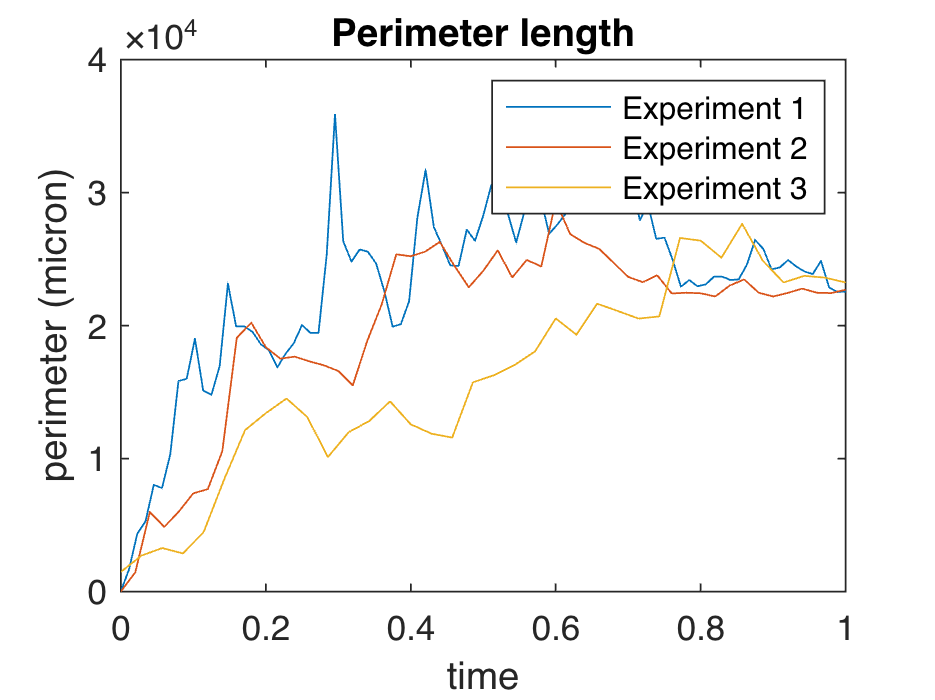

for i=1:length(experiments)
    plot(timeLines{i},perimeters{i});
    hold on;
end
hold off;
title("Perimeter length");
xlabel("time");
ylabel("perimeter (micron)");
legend("Experiment 1", "Experiment 2", "Experiment 3");

**Beta**

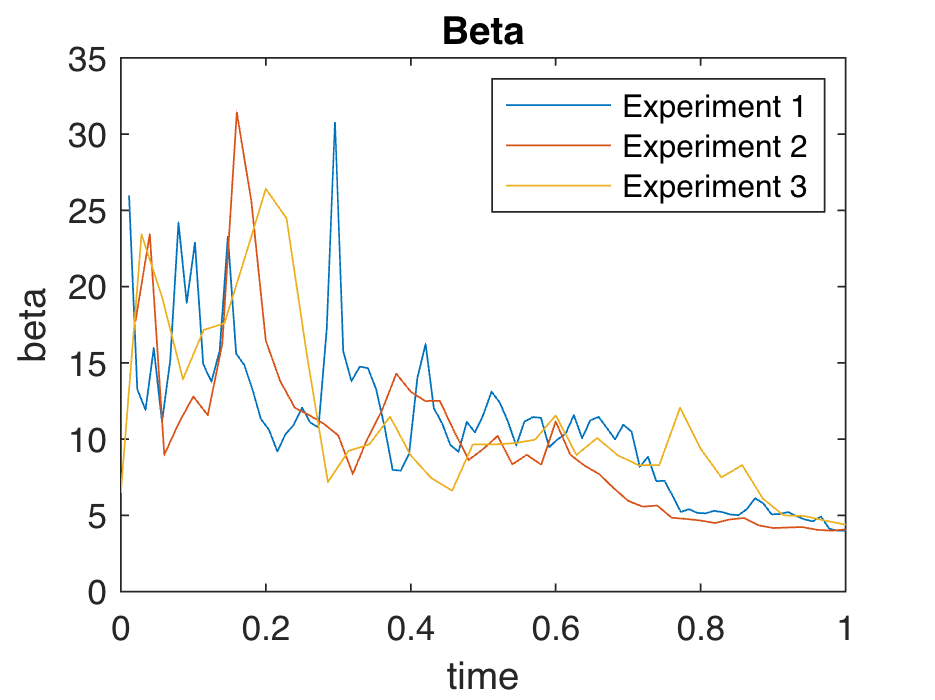

for i=1:length(experiments)
    plot(timeLines{i},betas{i});
    hold on;
end
hold off;
title("Beta");
xlabel("time");
ylabel("beta");
legend("Experiment 1", "Experiment 2", "Experiment 3");

**Perimeter for length**

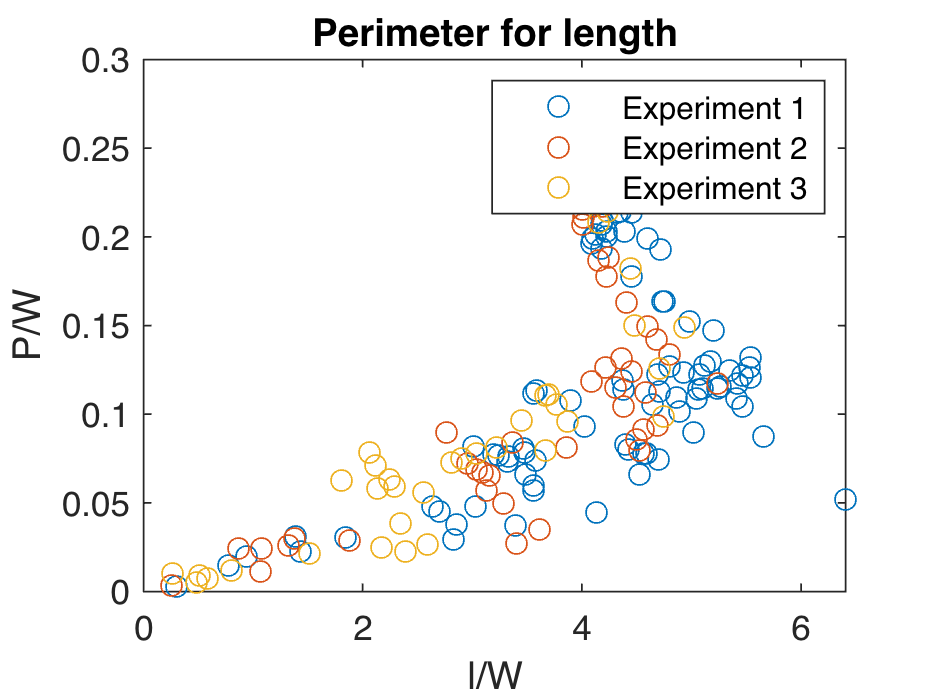

for i=1:length(thresholds)
    plot(perimeters{i} ./ lineWidth,lengths{i} ./ lineWidth,'o');
    hold on;
end
hold off;
title("Perimeter for length");
xlabel("l/W");
ylabel("P/W");
legend("Experiment 1", "Experiment 2", "Experiment 3");